clc;clear;
workingpath='/Volumes/WD_D/gufei/monkey_data/campwater';
cd(workingpath);

files=dir('*side.csv');
alldata=cell(1,length(files));
% middle point
m=zeros(1,length(files));
conditions=cell(1,length(files));
for f=1:length(files)
    % load data
    filename=files(f).name;
    % replace _ with -
    conditions{f}=strrep(filename(1:end-9),'_','-');
    % 从第二行第一列读取数据
    data=csvread(filename,1,0);
    m(f)=mean([min(data(:,2)) max(data(:,2))]);
    disp(filename)
    disp([min(data(:,2)) mean([min(data(:,2)) max(data(:,2))]) max(data(:,2)) min(data(:,3)) mean([min(data(:,3)) max(data(:,3))]) max(data(:,3))])
    % y is reversed
    data(:,3)=140-data(:,3);
    % 绘制轨迹
    % monkeyt(data(:,2),data(:,3),0.1,0.001);
    % 查看分布情况
    % length(data(data(:,2)>100,3));
    % length(data(data(:,2)<=100,3));
    % 
    % length(data(data(:,2)<=90,3));
    % length(data(data(:,2)>=110,3));
    % 
    % length(data(data(:,2)<=80,3));
    % length(data(data(:,2)>=120,3));
    % max(data(:,2));
    % min(data(:,2));
    % mean([max(data(:,2)),min(data(:,2))]);
    %保存到cell中
    alldata{f}=data;
end

吲哚_L_20201001_side.csv


   23.1664  122.3482  221.5300   60.9055   96.1718  131.4380



吲哚_R_20200930_side.csv


   21.9848  121.9749  221.9650   70.9609  100.5874  130.2140



异戊酸_L_20200929_side.csv


   19.6015  117.5563  215.5110   66.9861   97.6945  128.4030



异戊酸_R_20200926_side.csv


   23.3736  122.8108  222.2480   67.8863   99.7327  131.5790



白桃_L_20201003_side.csv


   19.3473  113.9021  208.4570   71.3002  100.3326  129.3650



白桃_R_20201004_side.csv


   18.9209  112.4839  206.0470   72.9749  100.4169  127.8590



香蕉_L_20201008_side.csv


   56.0087  110.5508  165.0930   80.2424   95.7127  111.1830



香蕉_R_20201009_side.csv


   20.6690  123.1115  225.5540   57.2239   94.2035  131.1830



## Scale

for f=1:length(files)
    data=alldata{f};
    mid=m(f);
    minvalue=min(data(:,2));
    maxvalue=max(data(:,2));
    data(data(:,2)<=mid,2)=(data(data(:,2)<=mid,2)-minvalue)*100/(mid-minvalue);    
    data(data(:,2)>mid,2)=100+(data(data(:,2)>mid,2)-mid)*100/(maxvalue-mid);    
    alldata{f}=data;
end

## 绘制轨迹

% for f=1:length(files)
%     data=alldata{f};
%     figure;
%     % 绘制轨迹
%     % monkeyt(data(:,2),data(:,3),0.1,0.001);
%     monkeyt(data(:,2),data(:,3),0,0);
%     title(conditions{f});
% end

## 整体的直方图

吲哚-L-20201001


   100   100



pvalue = 0

st =     chi2stat: 2.6316e+04
          df: 1
       edges: [0 100 200]
           O: [70001 21051]
           E: [45526 45526]


    90   110



pvalue = 0

st =     chi2stat: 2.7371e+04
          df: 1
       edges: [0 100 200]
           O: [69326 19906]
           E: [44616 44616]


    80   120



pvalue = 0

st =     chi2stat: 3.0080e+04
          df: 1
       edges: [0 100 200]
           O: [68785 17762]
           E: [4.3274e+04 4.3274e+04]


吲哚-R-20200930


   100   100



pvalue = 0

st =     chi2stat: 1.0479e+04
          df: 1
       edges: [0 100 200]
           O: [61363 30360]
           E: [4.5862e+04 4.5862e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.0758e+04
          df: 1
       edges: [0 100 200]
           O: [60759 29584]
           E: [4.5172e+04 4.5172e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.1667e+04
          df: 1
       edges: [0 100 200]
           O: [60110 28040]
           E: [44075 44075]


异戊酸-L-20200929


   100   100



pvalue = 0

st =     chi2stat: 1.5679e+04
          df: 1
       edges: [0 100 200]
           O: [63861 26269]
           E: [45065 45065]


    90   110



pvalue = 0

st =     chi2stat: 1.5793e+04
          df: 1
       edges: [0 100 200]
           O: [63404 25858]
           E: [44631 44631]


    80   120



pvalue = 0

st =     chi2stat: 1.8163e+04
          df: 1
       edges: [0 100 200]
           O: [62956 23361]
           E: [4.3158e+04 4.3158e+04]


异戊酸-R-20200926


   100   100



pvalue = 0

st =     chi2stat: 7.3309e+03
          df: 1
       edges: [0 100 200]
           O: [62716 35837]
           E: [4.9276e+04 4.9276e+04]


    90   110



pvalue = 0

st =     chi2stat: 7.5099e+03
          df: 1
       edges: [0 100 200]
           O: [62208 35166]
           E: [48687 48687]


    80   120



pvalue = 0

st =     chi2stat: 9.1177e+03
          df: 1
       edges: [0 100 200]
           O: [61365 32163]
           E: [46764 46764]


白桃-L-20201003


   100   100



pvalue = 0

st =     chi2stat: 1.7864e+04
          df: 1
       edges: [0 100 200]
           O: [66455 25848]
           E: [4.6152e+04 4.6152e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.7004e+04
          df: 1
       edges: [0 100 200]
           O: [63794 24948]
           E: [44371 44371]


    80   120



pvalue = 0

st =     chi2stat: 1.8063e+04
          df: 1
       edges: [0 100 200]
           O: [62077 22899]
           E: [42488 42488]


白桃-R-20201004


   100   100



pvalue = 0

st =     chi2stat: 1.9502e+04
          df: 1
       edges: [0 100 200]
           O: [72541 28214]
           E: [5.0378e+04 5.0378e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.0618e+04
          df: 1
       edges: [0 100 200]
           O: [71846 26757]
           E: [4.9302e+04 4.9302e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.2556e+04
          df: 1
       edges: [0 100 200]
           O: [70754 24421]
           E: [4.7588e+04 4.7588e+04]


香蕉-L-20201008


   100   100



pvalue = 0

st =     chi2stat: 2.3499e+04
          df: 1
       edges: [0 100 200]
           O: [69537 22924]
           E: [4.6230e+04 4.6230e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.4003e+04
          df: 1
       edges: [0 100 200]
           O: [68543 21940]
           E: [4.5242e+04 4.5242e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.4932e+04
          df: 1
       edges: [0 100 200]
           O: [67629 20701]
           E: [44165 44165]


香蕉-R-20201009


   100   100



pvalue = 1.7742e-38

st =     chi2stat: 168.2609
          df: 1
       edges: [0 100 200]
           O: [47053 43157]
           E: [45105 45105]


    90   110



pvalue = 7.1675e-39

st =     chi2stat: 170.0632
          df: 1
       edges: [0 100 200]
           O: [46739 42836]
           E: [4.4788e+04 4.4788e+04]


    80   120



pvalue = 1.2341e-50

st =     chi2stat: 223.9659
          df: 1
       edges: [0 100 200]
           O: [46149 41713]
           E: [43931 43931]


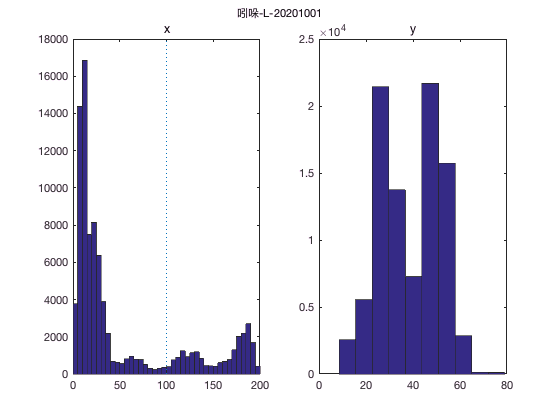

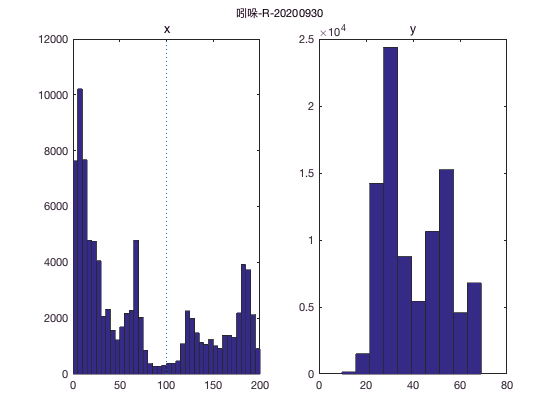

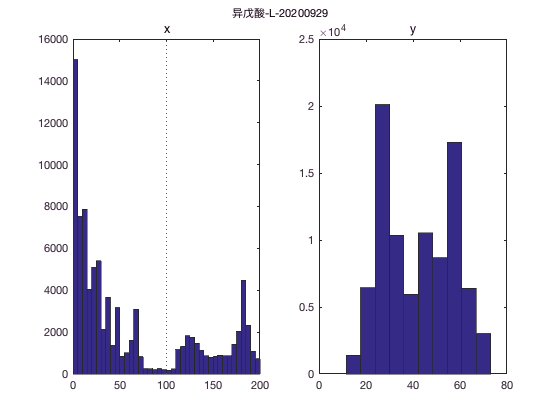

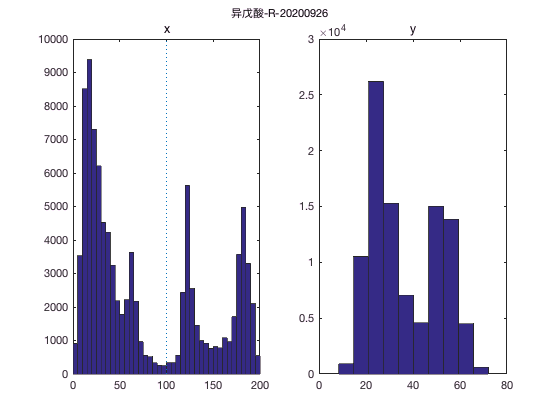

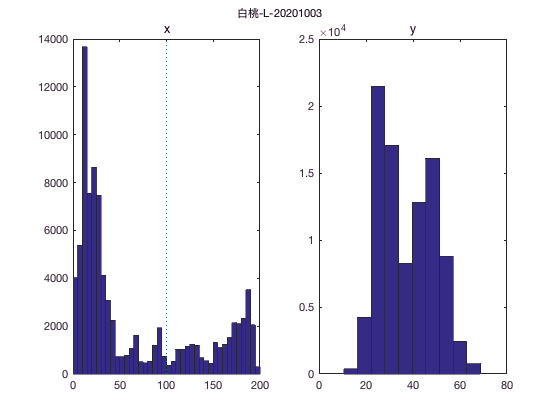

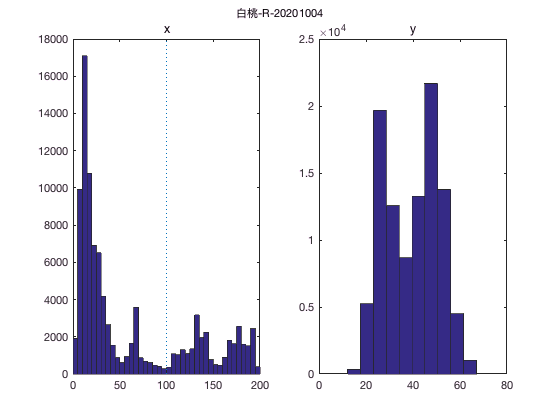

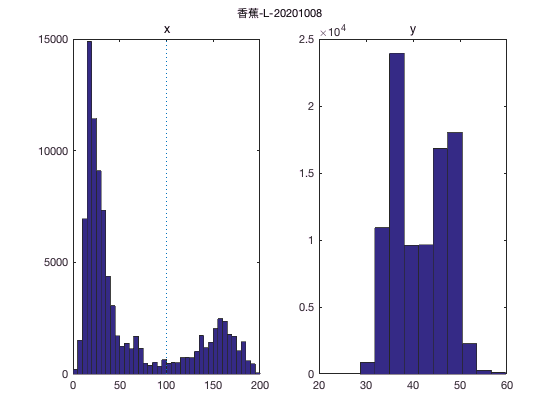

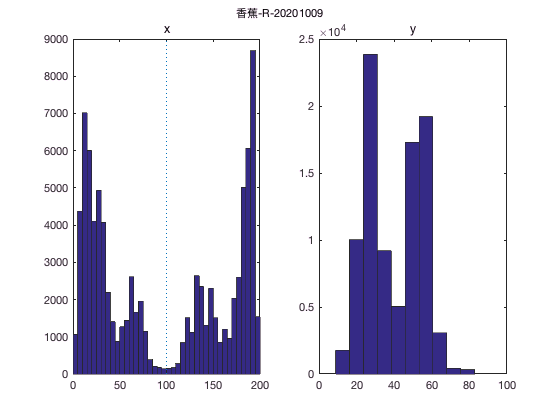

interval=5;
for f=1:length(files)
    data=alldata{f};
    % chisq test
    disp(conditions{f})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        % chit-chisquare test
        [pvalue,st]=chit(data,cutl,cutr)
    end
    figure;
    % x方向的分布
    subplot(1,2,1)
    hist(data(:,2),interval/2:interval:200-interval/2);
    line([100 100],get(gca,'Ylim'),'linestyle',':')
    title('x')
    % y方向的分布
    subplot(1,2,2)
    hist(data(:,3));
    title('y')
    suptitle(conditions{f});
end

## 合并4个条件

tic;
interval=10;
% concatenate all the data
data=cell2mat(alldata');
expect=zeros(3,2);
    % chisq test
    disp('all days');

all days


    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
        expect(i/10+1,:)=st.O;
    end

   100   100



pvalue = 0

st =     chi2stat: 1.0483e+05
          df: 1
       edges: [0 100 200]
           O: [513527 233660]
           E: [3.7359e+05 3.7359e+05]


    90   110



pvalue = 0

st =     chi2stat: 1.0658e+05
          df: 1
       edges: [0 100 200]
           O: [506619 226995]
           E: [366807 366807]


    80   120



pvalue = 0

st =     chi2stat: 1.1730e+05
          df: 1
       edges: [0 100 200]
           O: [499825 211060]
           E: [3.5544e+05 3.5544e+05]


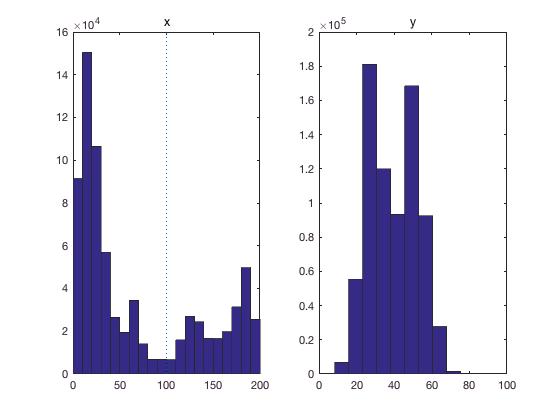


figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')

## 绘制热图

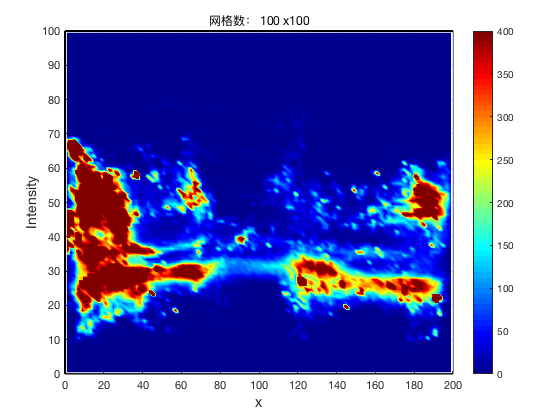

xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title(['网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');

toc;

时间已过 37.059978 秒。


## 合并odor两个条件

吲哚-L-20201001


   100   100



pvalue = 0

st =     chi2stat: 1.6239e+04
          df: 1
       edges: [0 100 200]
           O: [100361 82414]
           E: [1.2562e+05 5.7157e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.6420e+04
          df: 1
       edges: [0 100 200]
           O: [98910 80665]
           E: [1.2401e+05 5.5564e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.8544e+04
          df: 1
       edges: [0 100 200]
           O: [96825 77872]
           E: [1.2283e+05 5.1867e+04]


异戊酸-L-20200929


   100   100



pvalue = 0

st =     chi2stat: 2.2164e+04
          df: 1
       edges: [0 100 200]
           O: [99698 88985]
           E: [1.2968e+05 5.9005e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.3047e+04
          df: 1
       edges: [0 100 200]
           O: [98570 88066]
           E: [1.2889e+05 5.7749e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.6146e+04
          df: 1
       edges: [0 100 200]
           O: [95119 84726]
           E: [1.2645e+05 5.3396e+04]


白桃-L-20201003


   100   100



pvalue = 0

st =     chi2stat: 3.4830e+04
          df: 1
       edges: [0 100 200]
           O: [94669 98389]
           E: [1.3268e+05 6.0373e+04]


    90   110



pvalue = 0

st =     chi2stat: 3.7656e+04
          df: 1
       edges: [0 100 200]
           O: [90551 96794]
           E: [1.2938e+05 5.7968e+04]


    80   120



pvalue = 0

st =     chi2stat: 4.2901e+04
          df: 1
       edges: [0 100 200]
           O: [86498 93653]
           E: [1.2666e+05 5.3486e+04]


香蕉-L-20201008


   100   100



pvalue = 0

st =     chi2stat: 4.2072e+03
          df: 1
       edges: [0 100 200]
           O: [112694 69977]
           E: [1.2555e+05 5.7125e+04]


    90   110



pvalue = 0

st =     chi2stat: 4.3692e+03
          df: 1
       edges: [0 100 200]
           O: [111379 68679]
           E: [1.2434e+05 5.5714e+04]


    80   120



pvalue = 0

st =     chi2stat: 5.7472e+03
          df: 1
       edges: [0 100 200]
           O: [109342 66850]
           E: [1.2388e+05 5.2311e+04]


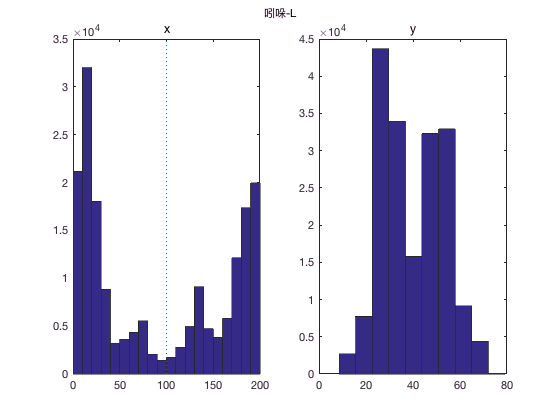

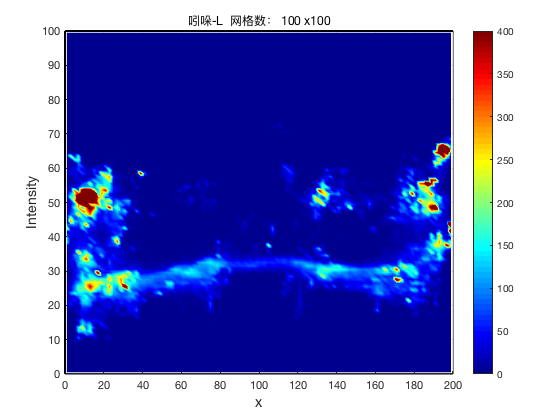

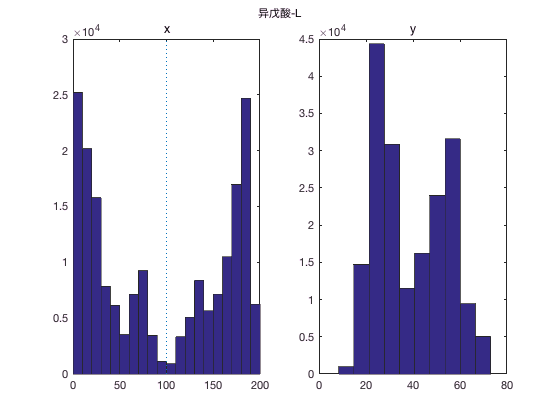

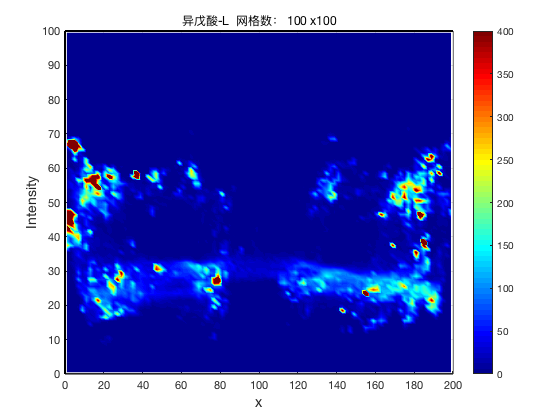

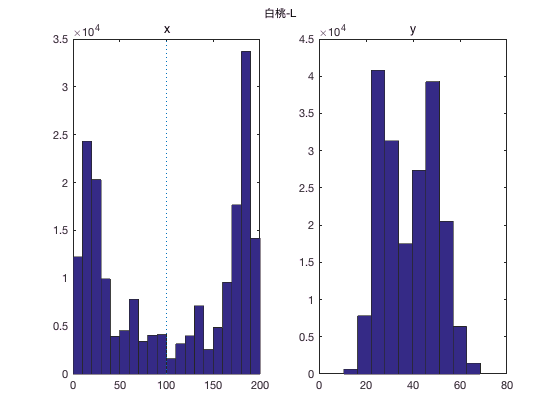

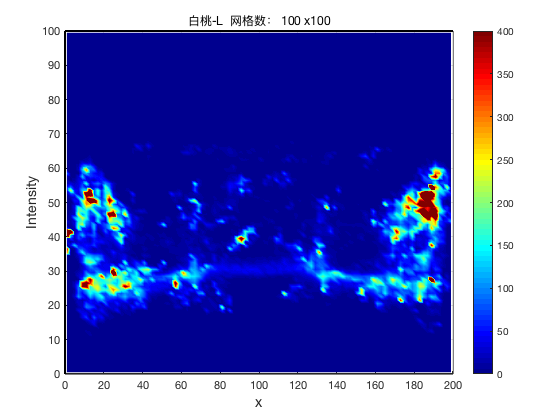

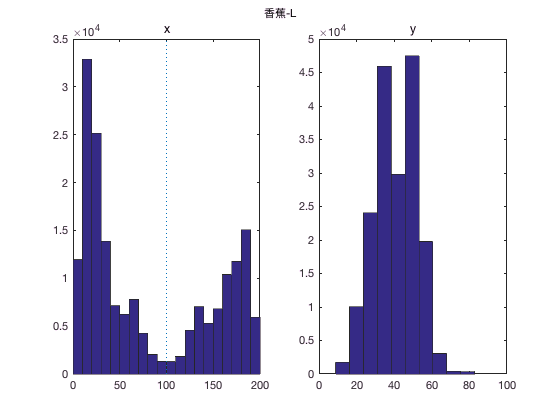

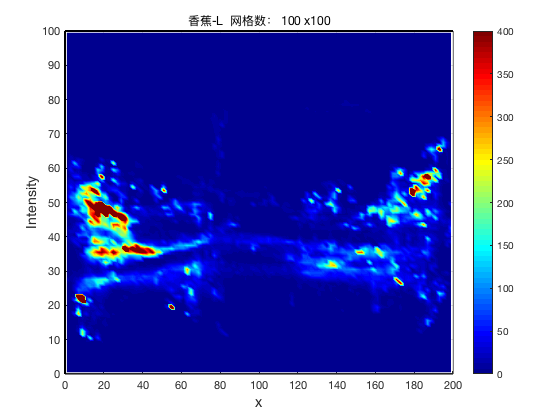

tic;
interval=10;
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1};data];

    % chisq test
    disp(conditions{odor-1})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr,expect(i/10+1,:))
    end

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
% 绘制热图
xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title([t(1:end-9) '  网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');
end

toc;

时间已过 50.035065 秒。


## 合并odor两个条件的（只取前面一段时间）

   100   100



pvalue = 0

st =     chi2stat: 1.9553e+03
          df: 1
       edges: [0 100 200]
           O: [14054 7554]
           E: [10804 10804]


   100   100



pvalue = 3.2995e-17

st =     chi2stat: 71.1567
          df: 1
       edges: [0 100 200]
           O: [8891 10052]
           E: [9.4715e+03 9.4715e+03]


   100   100



pvalue = 3.5172e-35

st =     chi2stat: 153.1696
          df: 1
       edges: [0 100 200]
           O: [10574 12452]
           E: [11513 11513]


   100   100



pvalue = 0

st =     chi2stat: 2.0962e+03
          df: 1
       edges: [0 100 200]
           O: [14024 7333]
           E: [1.0678e+04 1.0678e+04]


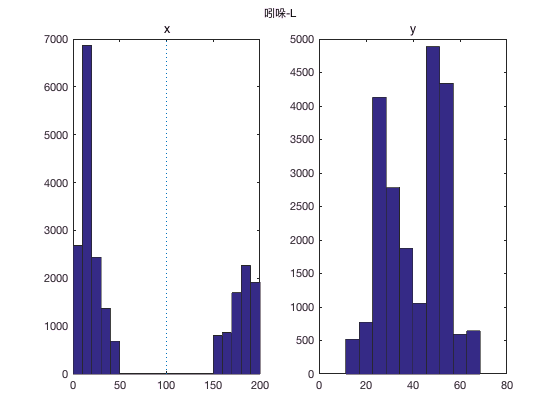

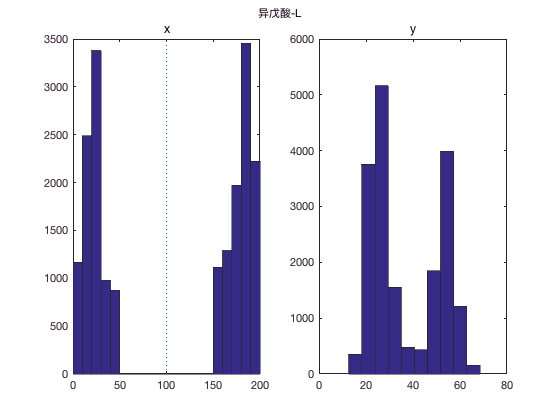

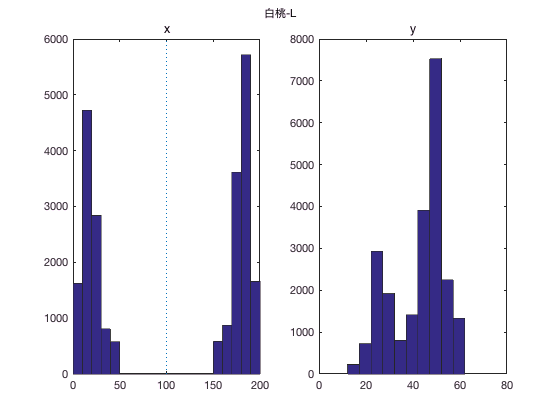

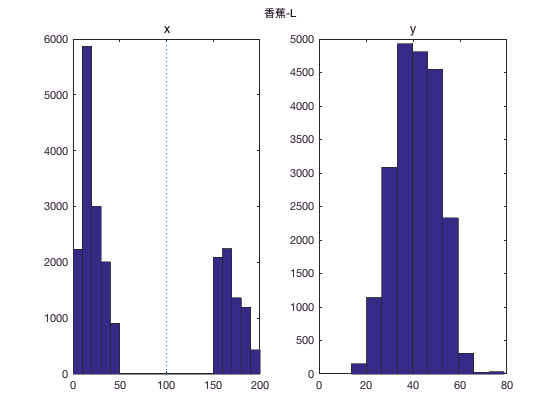

interval=10;
timeint=10;%minute
p1=1;
p2=timeint*60*1000/40;
% 1和3合并为1的方向
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1}(p1:p2,:);data(p1:p2,:)];
data=data(data(:,2)<=50|data(:,2)>=150,:);
    % chisq test
    for i=0
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])

        
        
        
        [pvalue,st]=chit(data,cutl,cutr)
    end
figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
end

## 分时段的分布直方图

吲哚-L-20201001


-------------


100-100


        9649        4001
       10587        3063
       10838        2812
       10277        3373
       10654        2996
       11242        2408
        6754        2398



  656.0782



  1.8531e-138



-------------


-------------


90-110


        9567        4083
       10506        3144
       10558        3092
       10210        3440
       10592        3058
       11186        2464
        6707        2445



  615.3586



  1.1339e-129



-------------


-------------


80-120


        9488        4162
       10434        3216
       10407        3243
       10120        3530
       10525        3125
       11137        2513
        6674        2478



  615.2835



  1.1770e-129



-------------


-------------


70-130


        9328        4322
       10334        3316
       10036        3614
        9902        3748
       10303        3347
       11008        2642
        6591        2561



  613.5724



  2.7538e-129



-------------


-------------


60-140


        8953        4697
       10109        3541
        9806        3844
        9600        4050
       10049        3601
       10773        2877
        6457        2695



  678.8996



  2.1973e-143



-------------


-------------


50-150


        8670        4980
        9898        3752
        9604        4046
        9433        4217
        9853        3797
       10571        3079
        6355        2797



  700.4968



  4.7780e-148



-------------


吲哚-R-20200930


-------------


100-100


        6951        6699
        8364        5286
        8927        4723
       11139        2511
        8004        5646
       10411        3239
        7567        2256



   4.5330e+03



     0



-------------


-------------


90-110


        6819        6831
        8263        5387
        8837        4813
       11073        2577
        7903        5747
       10338        3312
        7526        2297



   4.6310e+03



     0



-------------


-------------


80-120


        6676        6974
        8156        5494
        8752        4898
       10981        2669
        7801        5849
       10265        3385
        7479        2344



   4.7073e+03



     0



-------------


-------------


70-130


        6373        7277
        7340        6310
        8464        5186
       10495        3155
        7189        6461
       10014        3636
        7355        2468



   4.9926e+03



     0



-------------


-------------


60-140


        5523        8127
        5830        7820
        7287        6363
        9321        4329
        6477        7173
        9172        4478
        6540        3283



   4.6432e+03



     0



-------------


-------------


50-150


        4439        9211
        5426        8224
        6580        7070
        8626        5024
        6109        7541
        8744        4906
        6376        3447



   5.3047e+03



     0



-------------


异戊酸-L-20200929


-------------


100-100


        4928        8722
       10794        2856
        9432        4218
       10643        3007
       11625        2025
        9958        3692
        6481        1749



   1.0416e+04



     0



-------------


-------------


90-110


        4849        8801
       10599        3051
        9388        4262
       10600        3050
       11606        2044
        9917        3733
        6445        1785



   1.0345e+04



     0



-------------


-------------


80-120


        4759        8891
       10425        3225
        9341        4309
       10556        3094
       11587        2063
        9879        3771
        6409        1821



   1.0344e+04



     0



-------------


-------------


70-130


        4391        9259
       10319        3331
        9241        4409
       10446        3204
       11549        2101
        9791        3859
        6141        2089



   1.0959e+04



     0



-------------


-------------


60-140


        3315       10335
        9591        4059
        8639        5011
        9327        4323
       11462        2188
        8912        4738
        5935        2295



   1.2205e+04



     0



-------------


-------------


50-150


        2976       10674
        9470        4180
        8207        5443
        8863        4787
       11407        2243
        8614        5036
        5796        2434



   1.2607e+04



     0



-------------


异戊酸-R-20200926


-------------


100-100


        6439        7211
        8125        5525
        7783        5867
        8357        5293
        9348        4302
        9788        3862
       10320        3330
        2556         447



   3.9578e+03



     0



-------------


-------------


90-110


        6349        7301
        8061        5589
        7671        5979
        8282        5368
        9324        4326
        9708        3942
       10265        3385
        2548         455



   4.0283e+03



     0



-------------


-------------


80-120


        6256        7394
        8007        5643
        7475        6175
        8194        5456
        9281        4369
        9411        4239
       10201        3449
        2540         463



   3.9900e+03



     0



-------------


-------------


70-130


        6064        7586
        7902        5748
        7272        6378
        7885        5765
        9215        4435
        8953        4697
       10029        3621
        2524         479



   3.9483e+03



     0



-------------


-------------


60-140


        5343        8307
        6692        6958
        5614        8036
        6934        6716
        8917        4733
        8409        5241
        9624        4026
        2507         496



   5.8762e+03



     0



-------------


-------------


50-150


        4572        9078
        6370        7280
        4957        8693
        6561        7089
        8760        4890
        7950        5700
        8378        5272
        2494         509



   6.0557e+03



     0



-------------


白桃-L-20201003


-------------


100-100


        7534        6116
        8706        4944
        8924        4726
       10106        3544
       11860        1790
       10303        3347
        9022        1381



   5.3958e+03



     0



-------------


-------------


90-110


        7437        6213
        7972        5678
        7670        5980
        9962        3688
       11547        2103
       10216        3434
        8990        1413



   6.4671e+03



     0



-------------


-------------


80-120


        7352        6298
        7818        5832
        7262        6388
        9578        4072
       11238        2412
        9860        3790
        8969        1434



   6.2664e+03



     0



-------------


-------------


70-130


        7224        6426
        7615        6035
        7144        6506
        9444        4206
       11175        2475
        9591        4059
        8912        1491



   6.3240e+03



     0



-------------


-------------


60-140


        6879        6771
        6773        6877
        6866        6784
        9182        4468
       10867        2783
        9253        4397
        8584        1819



   6.4967e+03



     0



-------------


-------------


50-150


        6485        7165
        6561        7089
        6681        6969
        9076        4574
       10720        2930
        8949        4701
        8426        1977



   6.6676e+03



     0



-------------


白桃-R-20201004


-------------


100-100


        8286        5364
        8898        4752
        9537        4113
       10704        2946
        9567        4083
       10784        2866
       10297        3353
        4468         737



   2.4192e+03



     0



-------------


-------------


90-110


        8208        5442
        8827        4823
        9441        4209
       10661        2989
        9459        4191
       10706        2944
       10107        3543
        4437         768



   2.3759e+03



     0



-------------


-------------


80-120


        8128        5522
        8765        4885
        9385        4265
       10629        3021
        9002        4648
       10527        3123
        9914        3736
        4404         801



   2.3587e+03



     0



-------------


-------------


70-130


        8001        5649
        8682        4968
        9286        4364
       10539        3111
        8426        5224
       10345        3305
        9569        4081
        4342         863



   2.4359e+03



     0



-------------


-------------


60-140


        7697        5953
        8421        5229
        8930        4720
        9474        4176
        7958        5692
        9516        4134
        8438        5212
        3515        1690



  983.7610



  3.8841e-208



-------------


-------------


50-150


        7520        6130
        8253        5397
        8753        4897
        9294        4356
        7784        5866
        9321        4329
        8087        5563
        3389        1816



  967.8709



  1.0523e-204



-------------


香蕉-L-20201008


-------------


100-100


        9325        4325
        9722        3928
        9614        4036
       10118        3532
       10827        2823
       10786        2864
        9145        1416



   1.6036e+03



     0



-------------


-------------


90-110


        8977        4673
        9630        4020
        9517        4133
        9974        3676
       10635        3015
       10701        2949
        9109        1452



   1.7761e+03



     0



-------------


-------------


80-120


        8848        4802
        9557        4093
        9322        4328
        9853        3797
       10532        3118
       10638        3012
        8879        1682



   1.6330e+03



     0



-------------


-------------


70-130


        8749        4901
        9145        4505
        8844        4806
        9681        3969
       10252        3398
       10544        3106
        8775        1786



   1.8055e+03



     0



-------------


-------------


60-140


        8608        5042
        8984        4666
        7985        5665
        9179        4471
        9746        3904
       10084        3566
        8595        1966



   1.9172e+03



     0



-------------


-------------


50-150


        8301        5349
        8805        4845
        7450        6200
        8841        4809
        9429        4221
        9860        3790
        7875        2686



   1.5978e+03



     0



-------------


香蕉-R-20201009


-------------


100-100


        6256        7394
        6634        7016
        9161        4489
        6963        6687
        8365        5285
        7782        5868
        1892        6418



   4.9797e+03



     0



-------------


-------------


90-110


        6182        7468
        6551        7099
        9116        4534
        6917        6733
        8340        5310
        7743        5907
        1890        6420



   4.9608e+03



     0



-------------


-------------


80-120


        5965        7685
        6427        7223
        9045        4605
        6835        6815
        8301        5349
        7688        5962
        1888        6422



   4.9922e+03



     0



-------------


-------------


70-130


        5531        8119
        5493        8157
        8339        5311
        6282        7368
        8055        5595
        7458        6192
        1882        6428



   4.6370e+03



     0



-------------


-------------


60-140


        4501        9149
        4218        9432
        7692        5958
        5630        8020
        7842        5808
        7073        6577
        1811        6499



   5.5064e+03



     0



-------------


-------------


50-150


        4067        9583
        3593       10057
        6833        6817
        5249        8401
        7687        5963
        6859        6791
        1772        6538



   5.5656e+03



     0



-------------


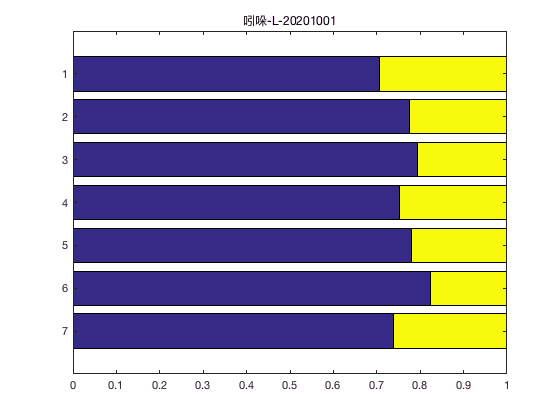

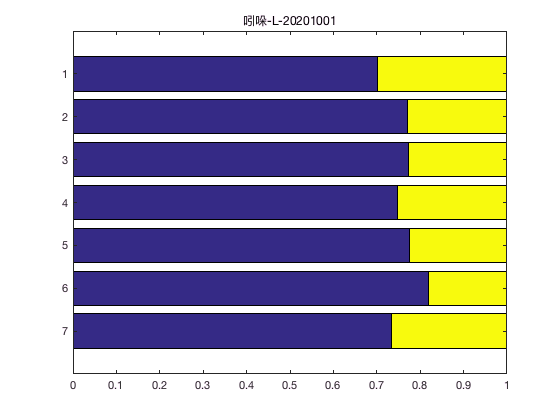

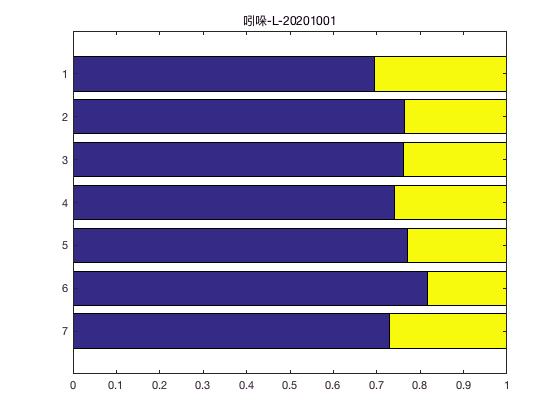

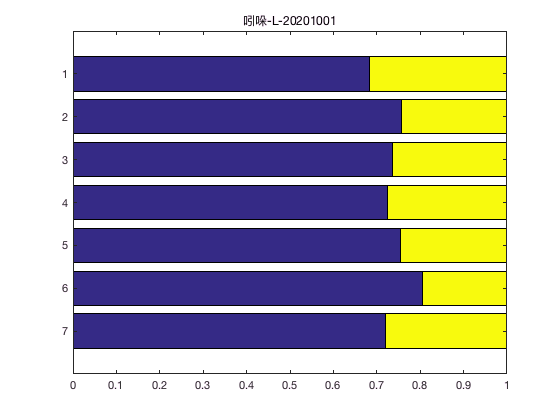

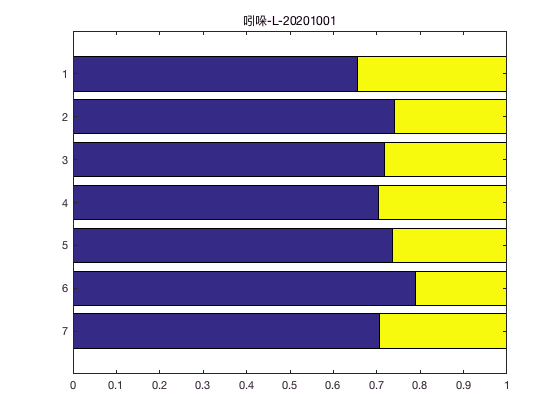

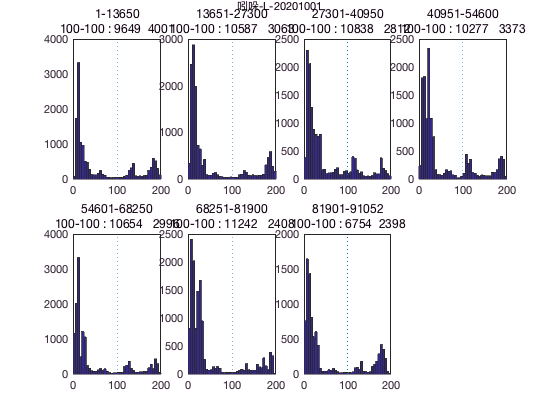

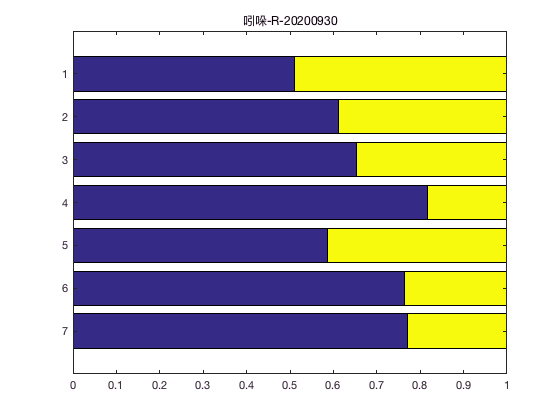

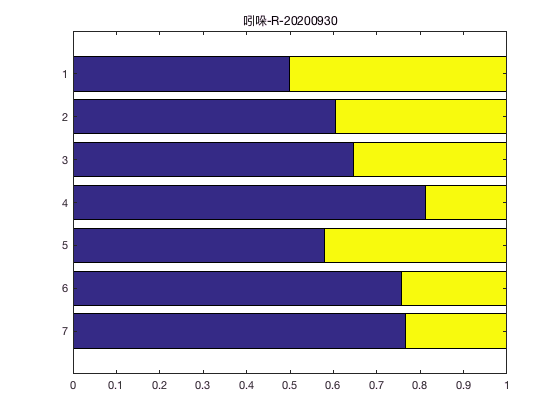

timeint=9.1;%minute
p=round(timeint*60*1000/40);
interval=5;
% plot each day
for f=1:length(files)
    data=alldata{f};
    l=length(data(:,2));
    plots=ceil(l/p);

    disp('===========================')
    disp(conditions{f})
    disp('===========================')
    for j=0:10:50
        timelab=zeros(1,l);
        leftright=timelab;
        cutl=100-j;
        cutr=100+j;
        leftright(data(:,2)<cutl)=1;
        leftright(data(:,2)>cutl)=2;
        for i=1:plots
            timelab(p*(i-1)+1:min(p*i,l))=i;                     
        end
        timelab(leftright==0)=[];
        leftright(leftright==0)=[];
        [tbl,chi2,pvalue] = crosstab(timelab,leftright);
        disp('-------------')
        disp([num2str(cutl) '-' num2str(cutr)])
        disp(tbl)
        disp(chi2)
        disp(pvalue)
        disp('-------------')
        % barplot
        percenttbl=tbl./sum(tbl,2);
        figure;
        barh(percenttbl,'stack')
        set(gca,'YDir','reverse')
        title(conditions{f})  
    end
    
    figure;
    set(gcf,'position',[1280,720,ceil(plots/2)*400,2*300]);
    % subplot each bin
    for i=1:plots
        subplot(2,ceil(plots/2),i)
        hist(data(p*(i-1)+1:min(p*i,l),2),interval/2:interval:200-interval/2)
        line([100 100],get(gca,'Ylim'),'linestyle',':')
%         disp('-------------')
%         disp([num2str(p*(i-1)+1) '-' num2str(min(p*i,l))])
%         
            % chisq test
        for j=0%:10:20
            cutl=100-j;
            cutr=100+j;
%             disp([cutl cutr])
            [pvalue,st]=chit(data(p*(i-1)+1:min(p*i,l),:),cutl,cutr);
        end
%         disp('-------------')
        
        title({[num2str(p*(i-1)+1) '-' num2str(min(p*i,l))];[num2str(cutl) '-' num2str(cutr) ' : ' num2str(st.O)]})
    end
    suptitle({conditions{f};''});
end